# Calculate cross section LF

## Set atom and magnetic field

setTestConfig(true)

% atom
atom = Alkali("Lithium7");

% B field
niB = 0.1e-4; %non-interacting feshbach field
bField = MagneticField(bias=[0;0;niB]);
bField = {bField};
stateList = atom.D2.BiasDressedStateList(bField{1});

## Set benchmark simulation

% resonant frequency
freq = atom.CyclerFrequency ...
    + stateList(stateList.F==3 & stateList.MF==3 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==2 & stateList.MF==2 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
psi = zeros(atom.D2.NNState,1);
psi(stateList(stateList.F==2 & stateList.MF==2 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% scan saturaction parameter
nLaser = 1;
sMin = 0.25;
sMax = 0.25;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 45;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(-1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    rotatingFrequency=freq,...
    totalTime = 0.5e-6);
me.Description = "Cross section calculation benchmark. Compare with two-level analytical results."

me =   MeSim with properties:

                    Atom: [1×1 Alkali]
                Manifold: "D2"
       RotatingFrequency: 4.4681e+14
             InitialTime: 0
               TotalTime: 5.0000e-07
                TimeStep: 4.9782e-12
              SavePeriod: 1000
           AveragePeriod: 10
                  Output: [3×3 table]
                WallTime: 41400
                  SimRun: [1×1 MeSimRun]
     UncompletedRunIndex: 1
             Description: "Cross section calculation benchmark. Compare with two-level analytical results."
           NCompletedRun: 0
                    NRun: 1
        ScannedParameter: "Saturation Parameter"
    ScannedParameterUnit: <missing>
                DateTime: 29-Nov-2023 16:41:38
                DataPath: "C:\data\meSim\crossSectionLi7\20231129_15"
              ObjectPath: "C:\data\meSim\crossSectionLi7\20231129_15\dataAnalysis\crossSectionLi720231129_15.mat"
               Tria

me.update
me.start

All runs are completed.


## Set repump simulation

% initial condition
psi = zeros(atom.D2.NNState,1);
psi(stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% resonant frequency
freq = atom.RepumperFrequency ...
    + stateList(stateList.F==2 & stateList.MF==2 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.RepumperSaturationIntensity;

% scan saturaction parameter
nLaser = 1;
sMin = 1;
sMax = 1;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 90;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = [0;1;0],...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("repumpLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    rotatingFrequency=freq,...
    totalTime = 10e-6);
me.update
me.start

## Set cross section simulation

% resonant frequency
freq = atom.CyclerFrequency ...
    + stateList(stateList.F==3 & stateList.MF==3 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==2 & stateList.MF==2 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
obj = loadTrial(createReader("simulation"),"master_equation_simulation",6);
rho = obj.SimRun.readRun("FinalDensityMatrix");
rho = (rho + rho')/2;
ic = InitialCondition("MeSim");
ic.DensityMatrix = rho;

% scan saturaction parameter
nLaser = 12;
sMin = 0.01;
sMax = 0.5;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 45;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(-1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    rotatingFrequency=freq,...
    totalTime = 5e-6);
me.Description = "Calculate Li7 cross section. Probe light pointing at z."

me =   MeSim with properties:

                    Atom: [1×1 Alkali]
                Manifold: "D2"
       RotatingFrequency: 446810635822413
             InitialTime: 0
               TotalTime: 5e-06
                TimeStep: 4.97819496715426e-12
              SavePeriod: 1000
           AveragePeriod: 10
                  Output: [3×3 table]
                WallTime: 41400
                  SimRun: [1×12 MeSimRun]
             Description: "Calculate Li7 cross section. Probe light pointing at z."
           NCompletedRun: 0
                    NRun: 12
        ScannedParameter: "Saturation Parameter"
    ScannedParameterUnit: <missing>
                DateTime: 20-Nov-2023 01:00:49
                DataPath: "C:\data\meSim\crossSectionLi7\20231120_5"
              ObjectPath: "C:\data\meSim\crossSectionLi7\20231120_5\dataAnalysis\crossSectionLi720231120_5.mat"
               TrialName: "crossSectionLi7"
            Serial

me.update
me.start

ans =  FevalOnAllFuture with properties: 

                   ID: 34
             Function: @warning
       CreateDateTime: 20-Nov-2023 01:01:57
        StartDateTime: 20-Nov-2023 01:01:57
      RunningDuration: 0 days 0h 0m 0s
                State: running
                Error: {}


## Plot

% plot benchmark
trialNumber = 2;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
obj.showCrossSection

ans =                       0.01        0.0545454545454545        0.0990909090909091         0.143636363636364         0.188181818181818         0.232727272727273         0.277272727272727         0.321818181818182         0.366363636363636         0.410909090909091         0.455454545454546                       0.5


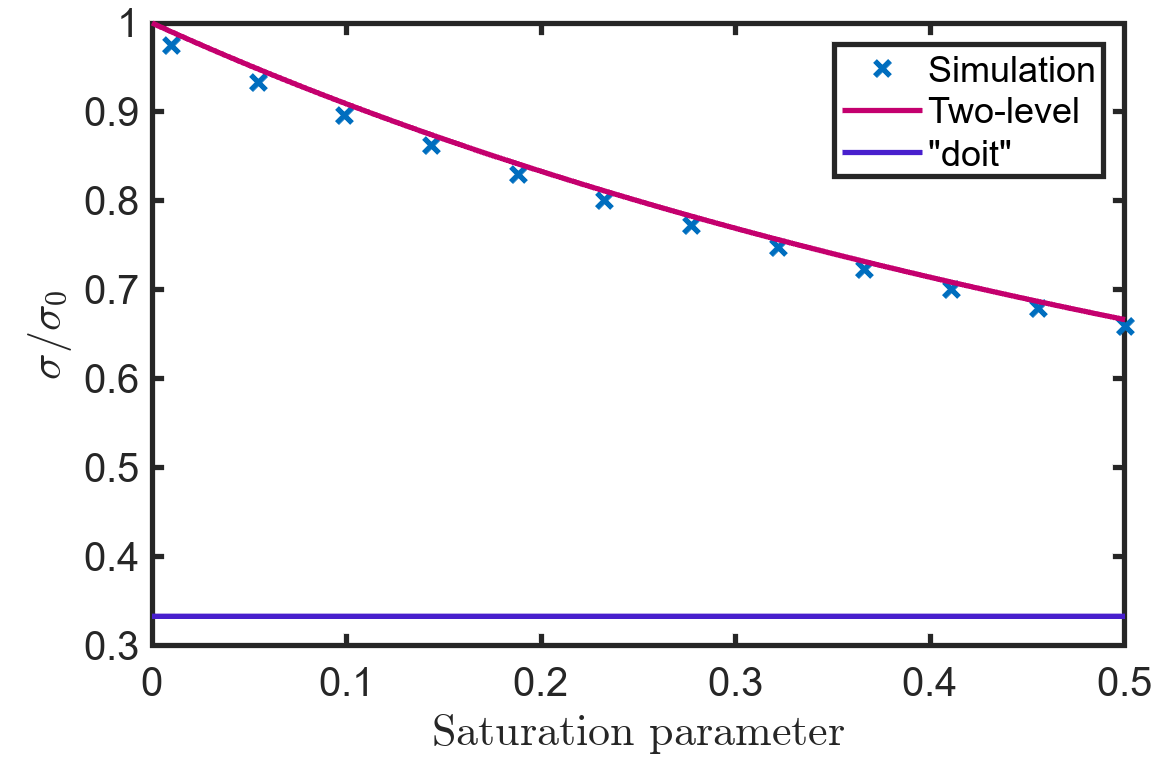

hold on 
sList0 = 0:0.005:0.5;
sigmaLis1 = 1./(1+sList0);
sigmaLis2 = ones(1,numel(sList0)) / 3;
plot(sList0,sigmaLis1,sList0,sigmaLis2,LineWidth=1.5)
hold off
legend("Simulation","Two-level","""doit""")
render
saveas(gcf,fullfile(obj.DataAnalysisPath,"benchmark.png"),'png')

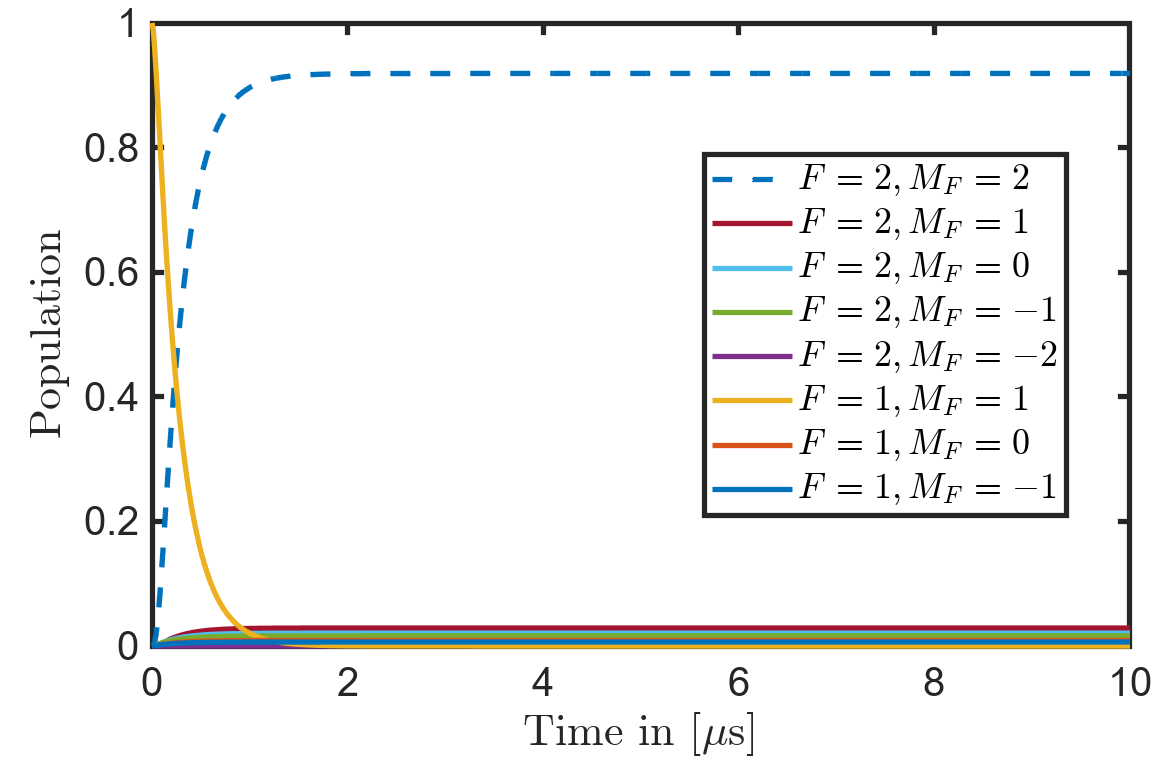


%plot repump
trialNumber = 6;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
obj.SimRun.showPopulationGround
saveas(gcf,fullfile(obj.DataAnalysisPath,"repump.png"),'png')

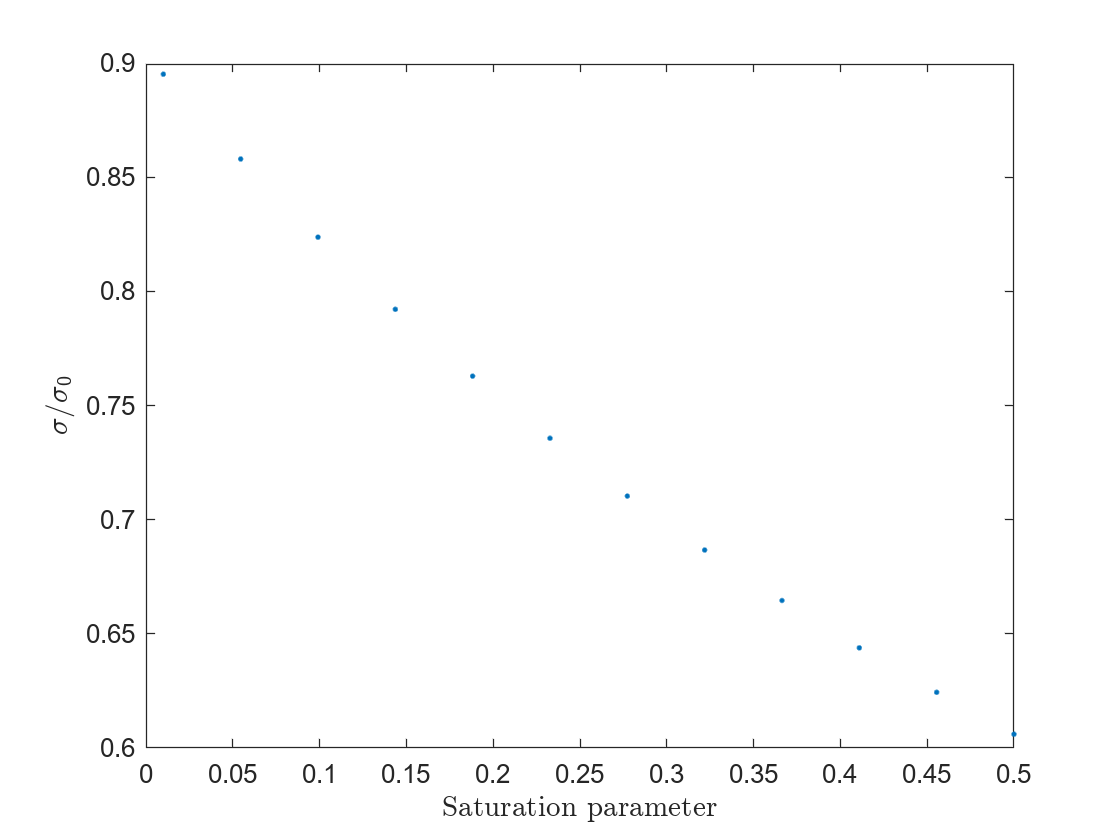


% plot cross section
trialNumber = 7;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp,s1] = obj.showCrossSection;

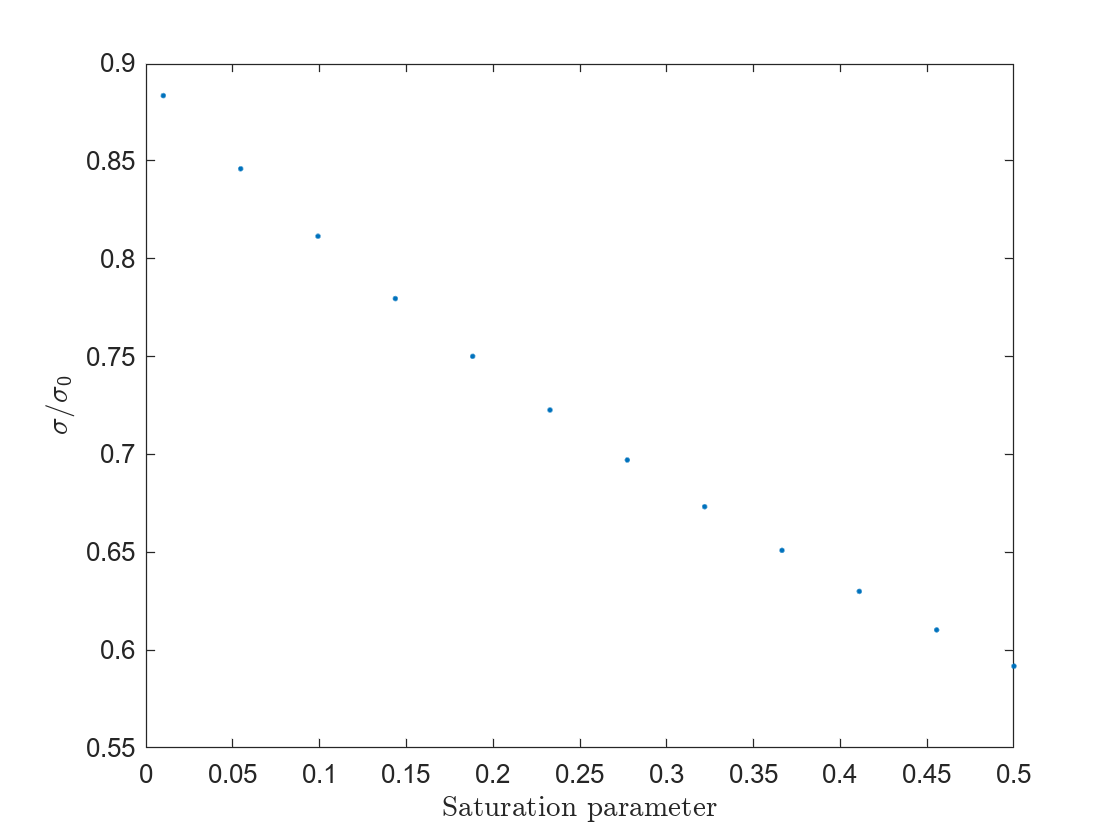


trialNumber = 8;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp,s2] = obj.showCrossSection;

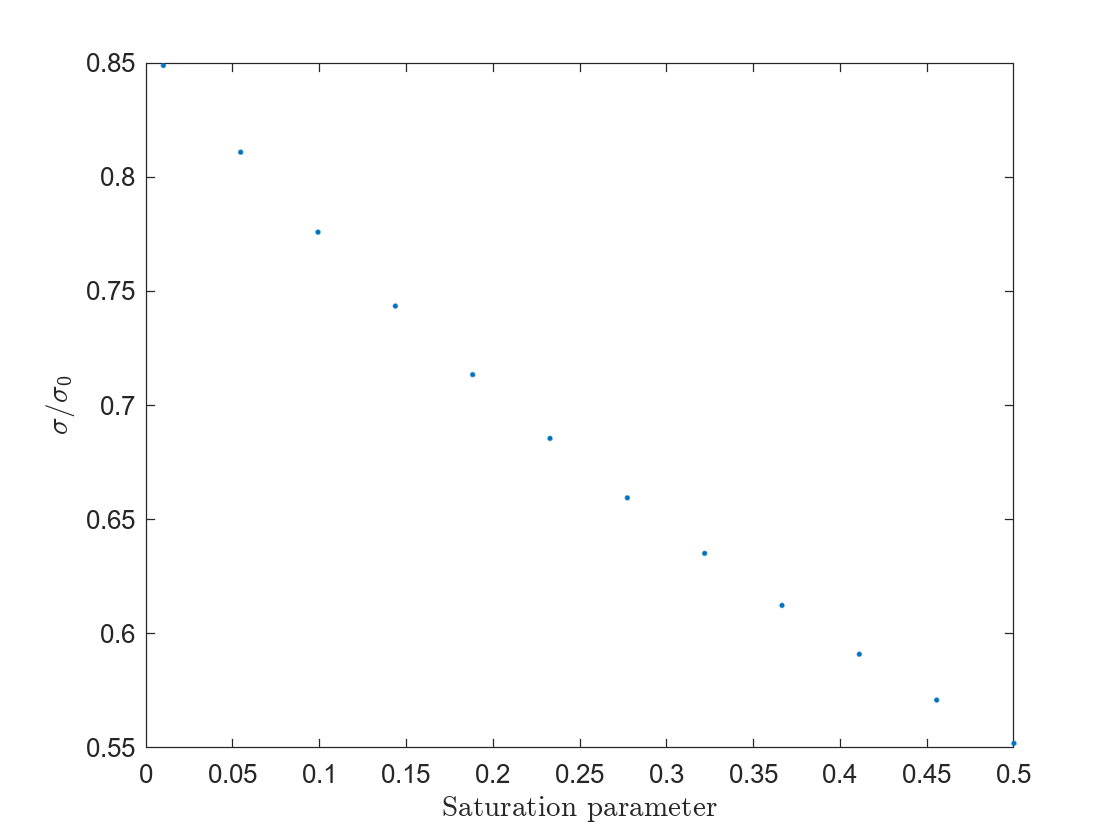


trialNumber = 9;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp,s3] = obj.showCrossSection;

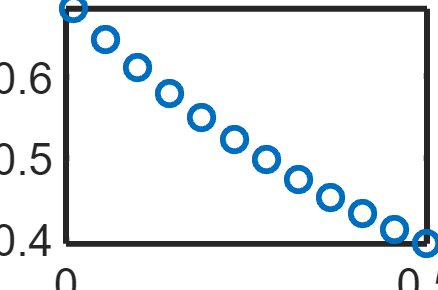


trialNumber = 10;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp,s4] = obj.showCrossSection;

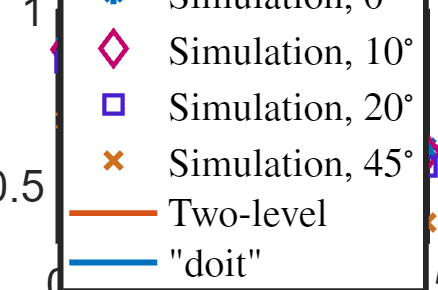


close(figure(2048))
figure(2048)
plot(sp,s1,'.',sp,s2,'.',sp,s3,'.',sp,s4,'.',sList0,sigmaLis1,sList0,sigmaLis2)
legend("Simulation, $0^{\circ}$",...
    "Simulation, $10^{\circ}$",...
    "Simulation, $20^{\circ}$",...
    "Simulation, $45^{\circ}$", ...
    "Two-level", ...
    """doit""")
xlabel("Saturation parameter",Interpreter="latex")
ylabel("$\sigma / \sigma_0$",Interpreter="latex")
render

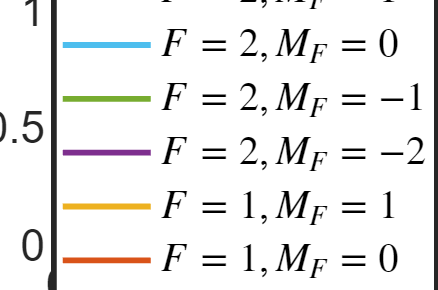


%plot population
trialNumber = 9;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
obj.SimRun(6).showPopulationGround
saveas(gcf,fullfile(obj.DataAnalysisPath,"popGround.png"),'png')

me.update